This live script is specificly designed for after_arrange(channels averaged data, only one sheet) PSD data in arranged out folder.

The whole purpose of this script is to average events data into one column, and put all data(different mice and condition) in a csv/xls. Sepearting each condition in sheets and concatinate mice data into one sheet. Like this:

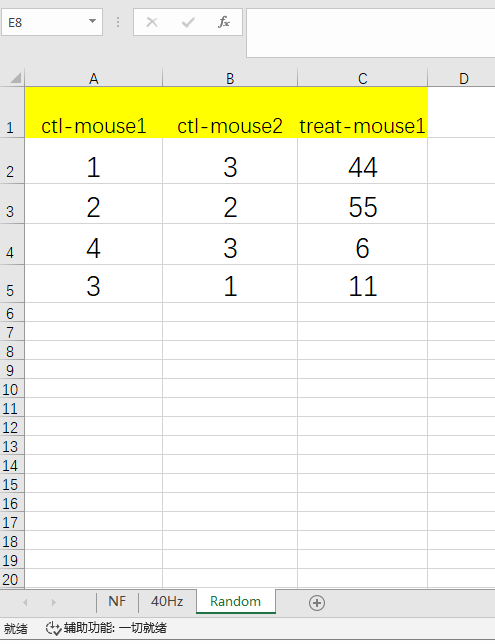

*update: forget about storing data in different sheets, thats stupid.

Let's go.

note: data value start at 2 row, 1st is the name! 

% first read all the arranged-data

x_wholedata = xlsread("PSD_out\40Hz\C57-A2646-40Hz.xlsx") % accquire x value first, for arranged data dont have x.

x_wholedata =          0   36.2529   34.4343   38.6663   34.3026   22.5099   41.1395   44.4392   39.2162   31.1658   27.1117
    0.1221   35.1377   35.1149   37.1593   34.6312   27.3394   41.5480   43.7752   38.6378   31.9244   28.0935
    0.2441   38.8034   36.4264   40.2595   36.3740   30.8596   42.1928   45.0522   39.4995   34.2264   33.6878
    0.3662   42.8971   39.9725   42.5767   35.8738   37.4572   45.1622   46.4941   42.7435   39.3500   38.4037
    0.4883   47.7652   41.1657   45.6602   42.1437   46.8134   49.3907   49.2056   42.6298   43.0769   45.1149
    0.6104   54.7037   47.8431   49.3335   42.5836   49.0600   54.5662   53.8955   46.5979   45.1710   47.2730
    0.7324   56.4491   49.1936   53.3195   52.7094   49.1175   53.9896   56.7461   48.0410   50.3974   51.3198
    0.8545   56.3691   51.6825   54.5353   52.8570   49.4608   55.4056   56.8823   47.7747   53.4633   53.1254
    0.9766   57.2043   52.2902   55.8717   56.1771   52.2772   55.3433   58.3005   47.5812   54.76

x_value = x_wholedata(:,1)

x_value =          0
    0.1221
    0.2441
    0.3662
    0.4883
    0.6104
    0.7324
    0.8545
    0.9766
    1.0986


marr_cell = {};

% collect file name
input_name = inputdlg('name of file:');
write_name = strcat(input_name{1},'.xls');

% select dir for putput
marr_out = uigetdir('','Select mean-arranged output folder')

marr_out = 'C:\Users\311\Documents\MATLAB\trash'


% get mutiple arranged files
[arr_file, arr_path] = uigetfile({'*.xlsx';'*.xls'}, ...
    'Slect an arranged file', ...
    'arrange_out\PSD\', ...
    'MultiSelect','on');

arr_tag = erase(arr_file, '.xlsx')

arr_tag = 1×4 cell array
    {'C57-A2646-8hz'}    {'C57-A2646-40Hz'}    {'C57-A2646-70Hz'}    {'C57-A2646-Random'}


arr_fullfile = fullfile(arr_path,arr_file)

arr_fullfile = 1×4 cell array
    {'C:\Users\311\Documents\MATLAB\arrange_out\PSD\C57-A2646-8hz.xlsx'}    {'C:\Users\311\Documents\MATLAB\arrange_out\PSD\C57-A2646-40Hz.xlsx'}    {'C:\Users\311\Documents\MATLAB\arrange_out\PSD\C57-A2646-70Hz.xlsx'}    {'C:\Users\311\Documents\MATLAB\arrange_out\PSD\C57-A2646-Random.xlsx'}



event_number = 10; % number of event
data_len = 738; % note all data move foreward 1 space due to name tag！
Alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';
col_Letter = Alphabet(event_number + 1)

col_Letter = 'K'

range = strcat('B1:',col_Letter, num2str(data_len))

range = 'B1:K738'


for arri = 1:length(arr_file)
    arr_data = xlsread(arr_fullfile{arri},range) % read the arrange data
    marr_data = mean(arr_data,2) % mean of arr data
    marr_cell(:,1) = {arr_tag{arri}, marr_data}
    
    write_fullfile = fullfile(marr_out, write_name)
    write_sheet = 1;
    x_range = 'A2'; % x value remain same
    tag_data = marr_cell(1,:);
    tag_range = strcat(Alphabet(arri + 1),'1');
    value_data = cell2mat(marr_cell(2,:))
    value_range = strcat(Alphabet(arri + 1),'2');
    xlswrite(write_fullfile, x_value, write_sheet, x_range);
    xlswrite(write_fullfile, tag_data, write_sheet, tag_range); % write in name of mouse
    xlswrite(write_fullfile, value_data, write_sheet, value_range); % write in value
end

arr_data =    35.4046   41.1383   30.9167   30.9786   28.6003   35.2937   32.1202   33.8104   36.1832   33.6751
   34.6831   42.6202   29.9925   33.1169   31.2720   34.8919   34.0617   34.5120   35.8443   34.7756
   36.6608   41.7396   31.9424   36.7128   33.3708   38.0394   35.6024   37.3548   36.7669   36.3190
   39.8930   43.9621   38.3370   43.7793   40.6478   39.4151   42.9889   41.7673   40.6528   37.7718
   41.6063   49.1221   43.7455   48.4461   41.8081   44.6489   46.3262   45.8169   43.2058   42.9109
   48.7829   52.9450   46.7964   52.7347   44.1725   50.1030   50.8593   49.9039   46.5005   47.9882
   52.0379   55.8643   47.5314   56.0375   46.9409   52.4364   53.9221   52.1313   49.1520   51.3088
   52.4692   57.1596   48.5222   57.0956   50.7869   54.2471   57.5313   53.6107   53.0739   51.7697
   54.4981   57.9562   51.1230   58.2826   53.7260   56.7743   58.1015   55.1741   55.5414   53.4970
   55.0604   58.2025   52.4752   58.6160   55.8810   56.7173   59.7670   55.4447

marr_data =    33.8121
   34.5770
   36.4509
   40.9215
   44.7637
   49.0786
   51.7362
   53.6266
   55.4674
   56.4987


marr_cell = 2×1 cell array
    {'C57-A2646-8hz'}
    {738×1 double   }


write_fullfile = 'C:\Users\311\Documents\MATLAB\trash\test.xls'

value_data =    33.8121
   34.5770
   36.4509
   40.9215
   44.7637
   49.0786
   51.7362
   53.6266
   55.4674
   56.4987


arr_data =    28.6826   35.2268   37.7846   38.7033   25.8525   38.9858   39.8982   39.1304   33.8756   27.0086
   31.7070   34.8869   36.4371   38.8908   26.6049   39.1216   37.6605   38.4421   32.8850   28.1411
   36.3109   36.1921   41.3290   40.0529   31.2816   40.6283   39.7141   39.4536   35.7479   32.4777
   41.4551   39.6138   45.1123   40.3840   36.6482   44.2268   42.1790   42.4303   40.2254   36.8389
   45.8296   40.6612   49.3946   45.6712   45.6004   47.4955   44.9170   43.4233   44.0277   43.2985
   52.8805   45.2648   51.4445   47.8206   47.8247   52.7910   49.2610   45.6757   45.8698   46.8015
   55.4884   46.4253   54.8267   53.6169   47.9070   52.4010   52.7918   47.0626   49.8683   49.8466
   55.5101   49.4286   56.1475   53.7601   48.0441   53.8774   52.6460   48.1367   52.8925   51.9871
   56.0288   50.8556   57.9475   56.1860   49.9847   54.2342   54.8504   48.5997   53.2537   52.9571
   55.9369   51.5880   58.4790   57.2375   51.7290   55.6576   54.5704   51.5067

marr_data =    34.5148
   34.4777
   37.3188
   40.9114
   45.0319
   48.5634
   51.0234
   52.2430
   53.4898
   54.5965


marr_cell = 2×1 cell array
    {'C57-A2646-40Hz'}
    {738×1 double    }


write_fullfile = 'C:\Users\311\Documents\MATLAB\trash\test.xls'

value_data =    34.5148
   34.4777
   37.3188
   40.9114
   45.0319
   48.5634
   51.0234
   52.2430
   53.4898
   54.5965


arr_data =    31.5064   34.8277   27.8835   31.7481   27.2553   26.8753   33.4424   41.5106   29.2809   35.8049
   30.7267   36.4251   31.9273   31.9735   29.8173   26.8767   33.7673   41.5989   29.6700   35.4534
   31.7316   37.7201   33.9024   35.7634   31.7901   31.9671   37.6625   41.5774   30.5442   36.7025
   39.1899   43.7234   38.5692   38.5066   36.5229   39.7749   37.9286   49.0109   34.7240   40.9439
   46.6786   44.9050   45.8701   41.9132   45.6457   46.4001   47.1260   50.7922   45.9756   44.8086
   52.4519   47.1336   48.3078   50.2094   53.0044   48.9913   50.1498   53.5520   50.6883   50.0698
   56.4986   50.8938   51.4771   53.8845   55.5881   53.0899   52.4567   54.8299   51.3698   54.6801
   58.0496   53.5018   53.8754   55.2224   57.0831   55.9427   54.0367   57.6693   53.8873   55.3095
   59.4545   54.9461   53.9102   57.0442   59.2479   58.7167   55.1591   57.8841   54.7196   55.9129
   59.6305   55.7753   55.1352   58.4404   61.0991   60.1675   58.8585   59.9112

marr_data =    32.0135
   32.8236
   34.9361
   39.8894
   46.0115
   50.4558
   53.4768
   55.4578
   56.6995
   58.2533


marr_cell = 2×1 cell array
    {'C57-A2646-70Hz'}
    {738×1 double    }


write_fullfile = 'C:\Users\311\Documents\MATLAB\trash\test.xls'

value_data =    32.0135
   32.8236
   34.9361
   39.8894
   46.0115
   50.4558
   53.4768
   55.4578
   56.6995
   58.2533


arr_data =    37.6250   42.4174   30.2306   38.6688   42.0983   22.3722   27.6485   32.2184   43.3500   34.2137
   38.0415   41.6294   31.8329   37.4417   44.0592   22.2040   30.9117   34.4786   43.5953   36.7464
   39.2880   42.8822   36.3277   38.9853   45.1888   23.8840   35.0635   35.4646   43.7996   40.2210
   45.1513   45.7609   44.0506   38.2119   48.9884   23.1937   39.7353   38.9883   44.0621   45.3622
   50.0251   47.5870   48.9354   41.2696   52.2873   36.5515   44.2677   43.4443   51.0816   50.1129
   52.1984   52.4988   50.9651   46.4481   57.5681   39.1430   48.2942   47.3815   55.9774   52.6689
   54.4512   55.4069   54.1079   46.6742   57.0023   41.1592   49.7231   50.6953   56.1665   55.4674
   55.4436   56.1723   54.4076   49.0794   59.2441   43.8759   53.9421   53.8952   56.2526   55.3955
   56.7924   57.8066   55.2541   52.7003   58.8907   48.6574   55.9372   55.2093   56.4557   57.4616
   57.7720   57.9515   55.5576   55.3328   60.8008   51.3451   57.6013   56.0519

marr_data =    35.0843
   36.0941
   38.1105
   41.3505
   46.5562
   50.3143
   52.0854
   53.7708
   55.5165
   56.9254


marr_cell = 2×1 cell array
    {'C57-A2646-Random'}
    {738×1 double      }


write_fullfile = 'C:\Users\311\Documents\MATLAB\trash\test.xls'

value_data =    35.0843
   36.0941
   38.1105
   41.3505
   46.5562
   50.3143
   52.0854
   53.7708
   55.5165
   56.9254
